# Lab 0 - Introduction to MATLAB and the Image Processing Toolkit

Nick Snyder

## 1 Image Processing Toolbox (IPT) Basics

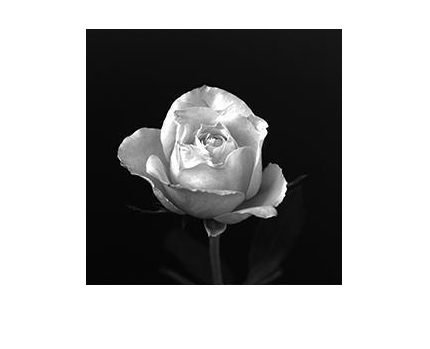

f = imread('rose256.tif');
imshow(f)

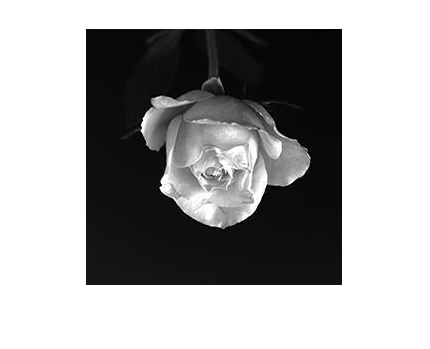

imwrite(imrotate(f, 180), 'rose256_upside_down.tif')
figure, imshow(imrotate(f, 180))

imfinfo('rose256_upside_down.tif')

ans = struct with fields:
                     Filename: 'C:\Users\no_kn\Documents\unh\coursework\ece717\rose256_upside_down.tif'
                  FileModDate: '24-Feb-2024 19:25:58'
                     FileSize: 29082
                       Format: 'tif'
                FormatVersion: []
                        Width: 256
                       Height: 256
                     BitDepth: 8
                    ColorType: 'grayscale'
              FormatSignature: [73 73 42 0]
                    ByteOrder: 'little-endian'
               NewSubFileType: 0
                BitsPerSample: 8
                  Compression: 'PackBits'
    PhotometricInterpretation: 'BlackIsZero'
                 StripOffsets: [8 3680 6998 12255 18058 23267 26762 27969]
              SamplesPerPixel: 1
                 RowsPerStrip: 32
              StripByteCounts: [3672 3318 5257 5803 5209 3495 1207 858]
                  XResolution: 72
                  YResolution: 72
               ResolutionUnit: 'Inch

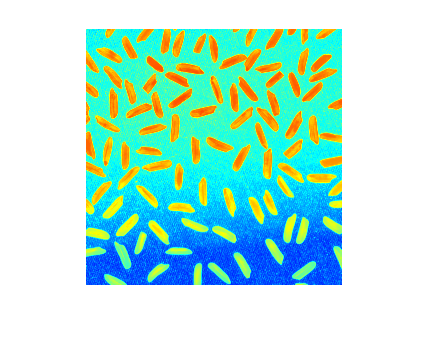

g = imread('rice256.png');
figure, imshow(g), colormap jet, figure, imshow(g)

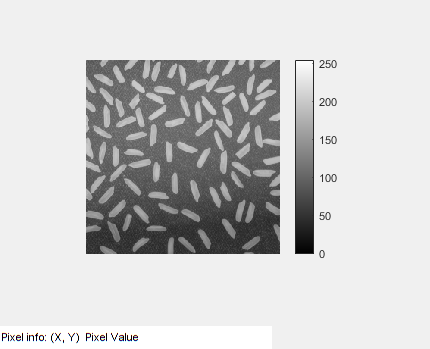

impixelinfo
colorbar

## Arithmetic Operations

imabsdiff() shows the absolute difference of each image.

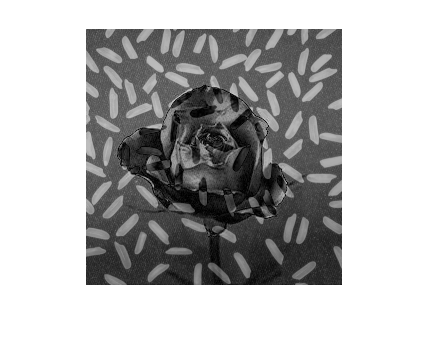

figure, imshow(imabsdiff(f, g))

imapplymatrix() shows a linear combination of color channels.

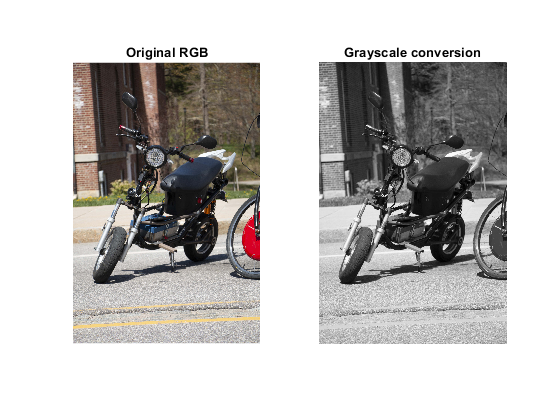

m = imread('moped.jpg');
M = [0.30, 0.59, 0.11];
gray = imapplymatrix(M, m);
figure
subplot(1,2,1), imshow(m), title('Original RGB')
subplot(1,2,2), imshow(gray), title('Grayscale conversion')

imcomplement() shows the complement of an image.

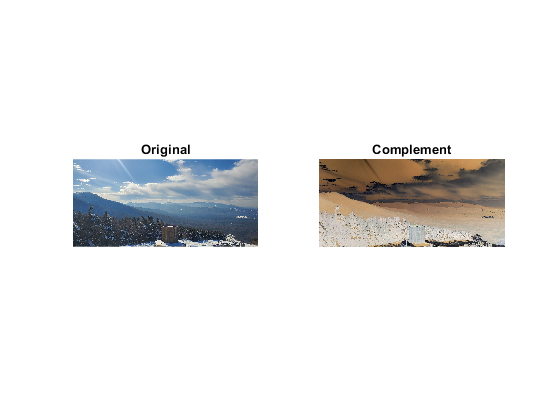

I = imread('mountain.jpg');
J = imcomplement(I);
figure
subplot(1,2,1), imshow(I), title('Original')
subplot(1,2,2), imshow(J), title('Complement')

imdivide() divides (darkens) an image by a constant

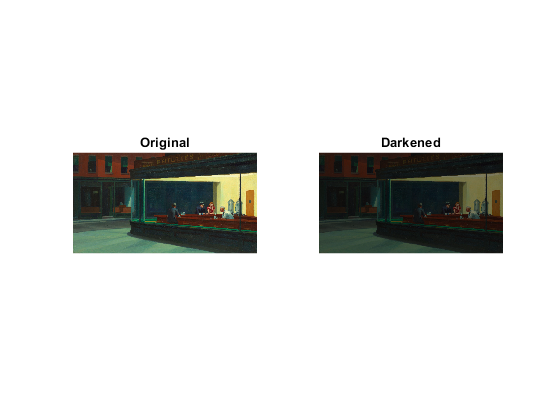

I = imread('nighthawks.jpg');
J = imdivide(I, 2);
figure
subplot(1,2,1), imshow(I), title('Original')
subplot(1,2,2), imshow(J), title('Darkened')

imlincomb() can brighten an image by a factor of two.

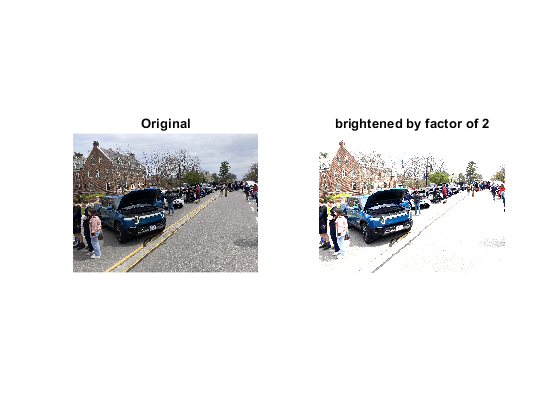

I = imread('rivian.JPG');
J = imlincomb(2, I);
figure
subplot(1,2,1), imshow(I), title('Original')
subplot(1,2,2), imshow(J), title('brightened by factor of 2')

immultiply() can can brighten an image by a factor of two.

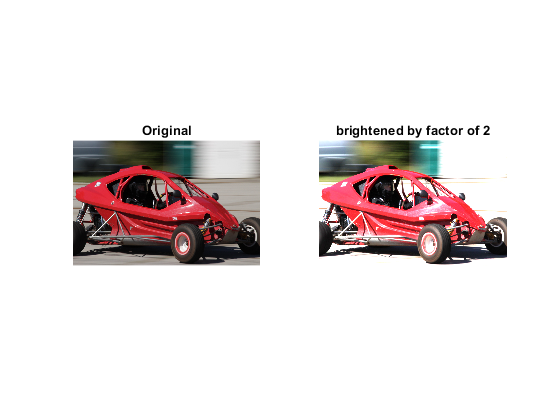

I = imread('crosskart.jpg');
J = immultiply(I, 2);
figure
subplot(1,2,1), imshow(I), title('Original')
subplot(1,2,2), imshow(J), title('brightened by factor of 2')

imsubtract() can subtract a constant value from an image:

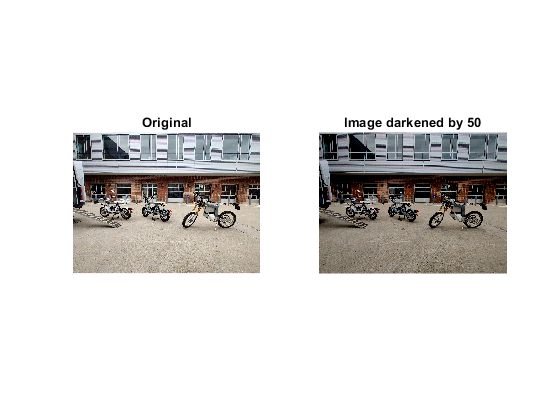

I = imread('cake.jpg');
Iq = imsubtract(I,50);
figure
subplot(1,2,1), imshow(I), title('Original')
subplot(1,2,2), imshow(Iq,[]), title('Image darkened by 50')

imadd() can add two images together.

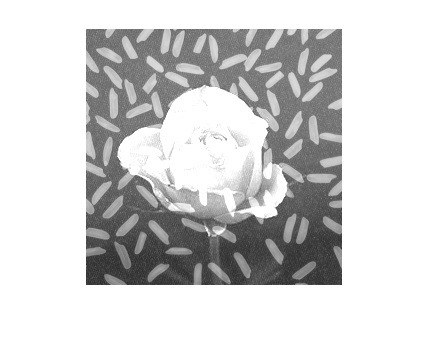

f = imread('rose256.tif');
g = imread('rice256.png');
figure, imshow(imadd(f, g))

In the result the rose and rice appear placed over eachother

## Exercise 1.1

f = imread('rose256.tif');
g = imread('rice256.png');

A., B. There is no difference between the pixel values in any of the images

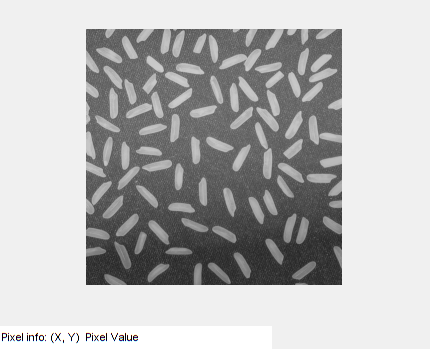

figure 
imshow(g)
impixelinfo

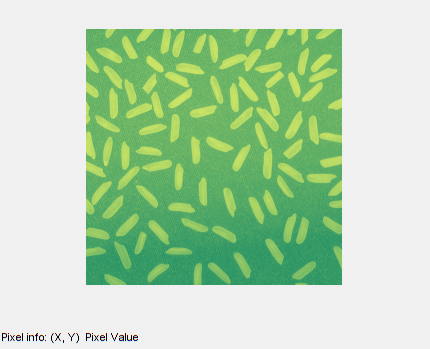

imshow(g), colormap summer
impixelinfo

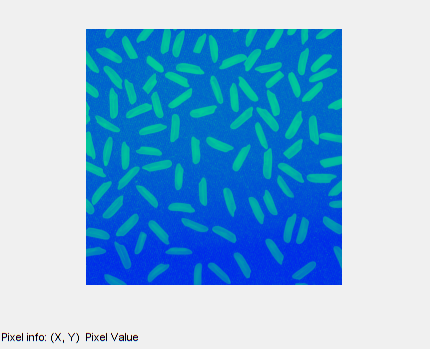

imshow(g), colormap winter
impixelinfo 

C.

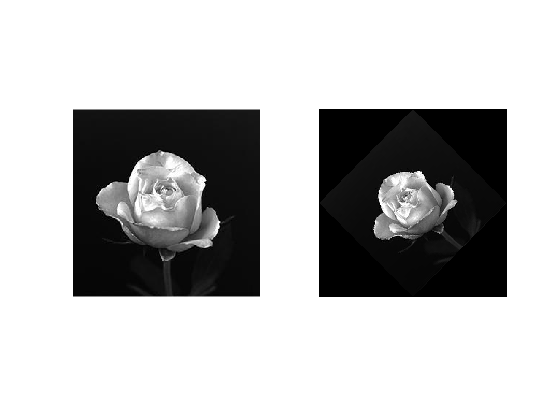

figure
imwrite(imrotate(f, 45), 'f11c.tif')
subplot(1,2,1), imshow(f)
subplot(1,2,2), imshow(imrotate(f, 45))

D.

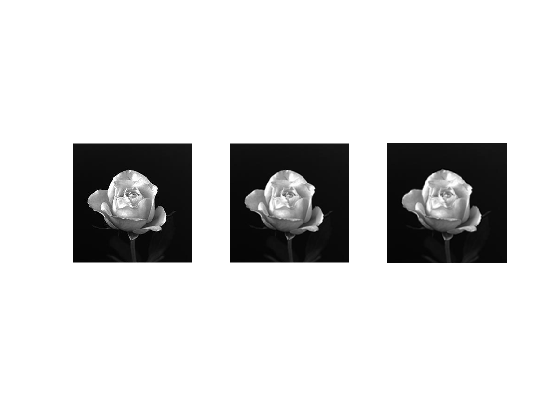

f_small = imresize(f, 0.5);
f_big = imresize(f_small, 2);
figure
subplot(1,3,1), imshow(f)
subplot(1,3,2), imshow(f_small)
subplot(1,3,3), imshow(f_big) 

f_small looks more blurry at the same resolution and f_big is as blurry as f_small but now at a higher resolution.

 E. 

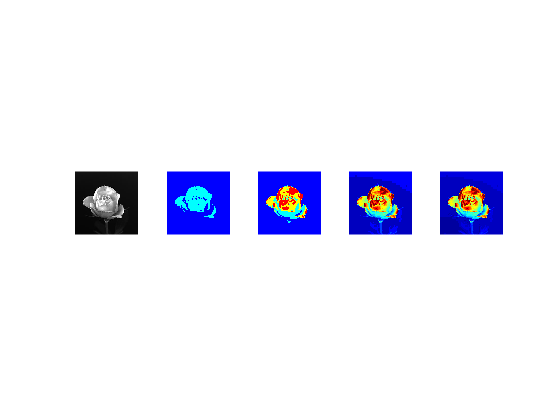

figure
subplot(1,5,1), imshow(f)
subplot(1,5,2), imshow(grayslice(f, 2), jet(2))
subplot(1,5,3), imshow(grayslice(f, 4), jet(4))
subplot(1,5,4), imshow(grayslice(f, 16), jet(16))
subplot(1,5,5), imshow(grayslice(f, 32), jet(32)) 

Without using jet() the images are completely black. With jet() each image has as many grey levels as the threshold states.

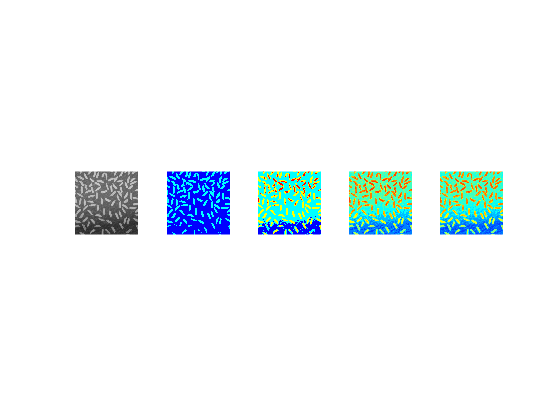

figure
subplot(1,5,1), imshow(g)
subplot(1,5,2), imshow(grayslice(g, 2), jet(2))
subplot(1,5,3), imshow(grayslice(g, 4), jet(4))
subplot(1,5,4), imshow(grayslice(g, 16), jet(16))
subplot(1,5,5), imshow(grayslice(g, 32), jet(32))

F.

imwrite(f, 'rose256.tif', 'jpg');
imwrite(g, 'rice256.tif', 'jpg');

## Exercise 1.2

A.

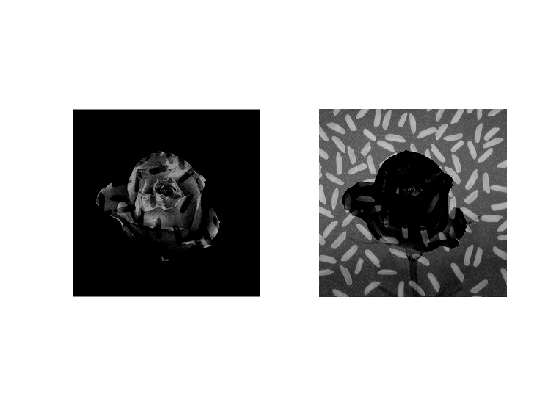

a = imsubtract(f, g);
b = imsubtract(g, f);
figure
subplot(1,2,1), imshow(a)
subplot(1,2,2), imshow(b)

B. 

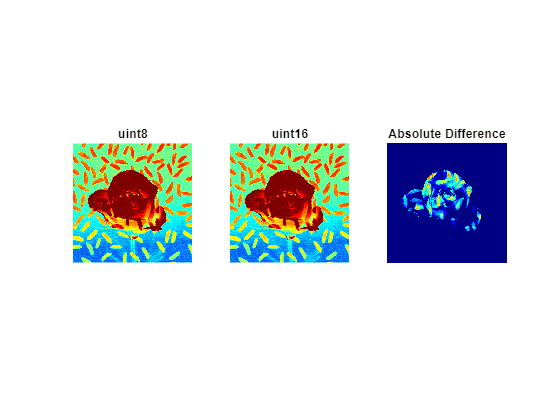

% c = cast(imadd(f, g), "uint16");
c = imadd(cast(f, 'uint16'), cast(g, 'uint16'));
figure
subplot(1,3,1), imshow(imadd(f, g), jet(256)), title('uint8')
subplot(1,3,2), imshow(c, jet(256)), title('uint16') 
subplot(1,3,3), imshow(imabsdiff(cast(imadd(f, g), "uint16"), c), jet(256)), title('Absolute Difference')

The images are very similar but differ depending on how the image is cast to uint16.

C.

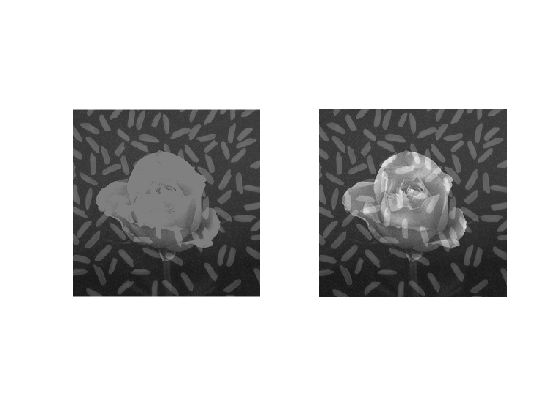

d = imdivide(imadd(f, g), 2);
e = imlincomb(0.5,f,0.5,g);
figure
subplot(1,2,1), imshow(d)
subplot(1,2,2), imshow(e)

D.

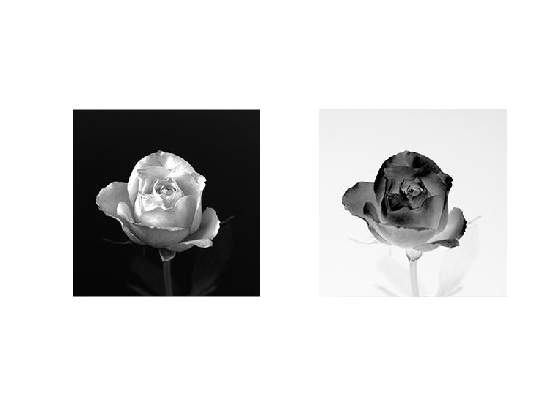

i = imcomplement(f);
figure
subplot(1,2,1), imshow(f)
subplot(1,2,2), imshow(i)

## Exercise 1.3

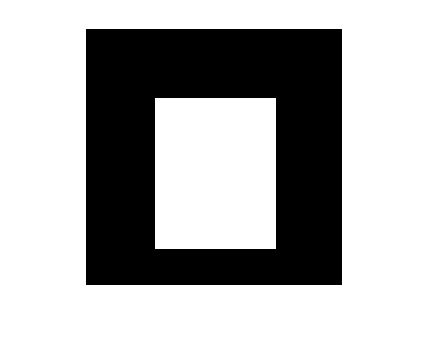

mask = false(256, 256);
mask(70:220, 70:190) = true;
figure
imshow(mask)

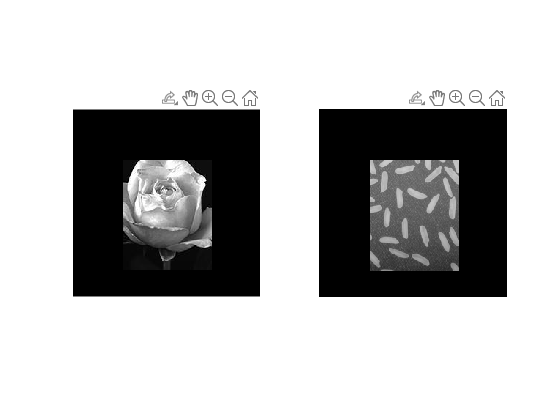

f_mask = immultiply(f, mask);
g_mask = immultiply(g, mask);
figure
subplot(1,2,1), imshow(f_mask)
subplot(1,2,2), imshow(g_mask) 

Cropping is useful to remove data you don't need. Cropping around a particular area of an image could help make a crude equalization of the image histogram.